# Scripts Fonctions de transfert

clear;clc;close all;
format shorteng; format compact;


Constantes

L = 1e-3;
C = 10e-6;
R = 2;


Définition de la fonction de transfert

num = [C, 0];
den = [L*C, R*C, 1];
sys = tf(num, den)

sys =
 
          1e-05 s
  -----------------------
  1e-08 s^2 + 2e-05 s + 1
 
Continuous-time transfer function.



**Transformée inverse** (besoin d'un addon "Inverse Laplace Transform of Transfer Function Class")

ilaplacetf(sys)

$$ans = 1000\,{\mathrm{e}}^{-1000\,t}\,\left(\cos\left(3000\,\sqrt{11}\,t\right)-\frac{\sqrt{11}\,\sin\left(3000\,\sqrt{11}\,t\right)}{33}\right)$$

## Décomposer en fractions partielles

Utilisé pour faire Laplace inverse

... = r1/p1 + r2/p2 + r3/p3 + k

[r p k] = residue(num, den)

r =    500.0000e+000 + 50.2519e+000i
   500.0000e+000 - 50.2519e+000i


p =  -1000.0000e+000 +  9.9499e+003i
 -1000.0000e+000 -  9.9499e+003i


k =
     []


## Esquisser la réponse indicielle

à un saut unité

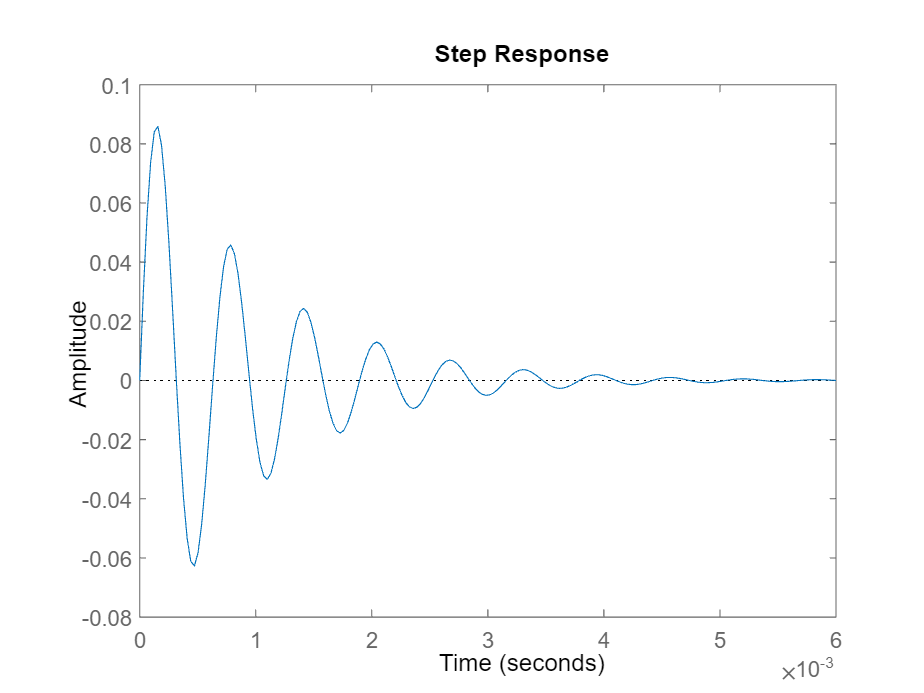

step(sys);

## Esquisser la réponse impulsionnelle

à une impulsion de dirac

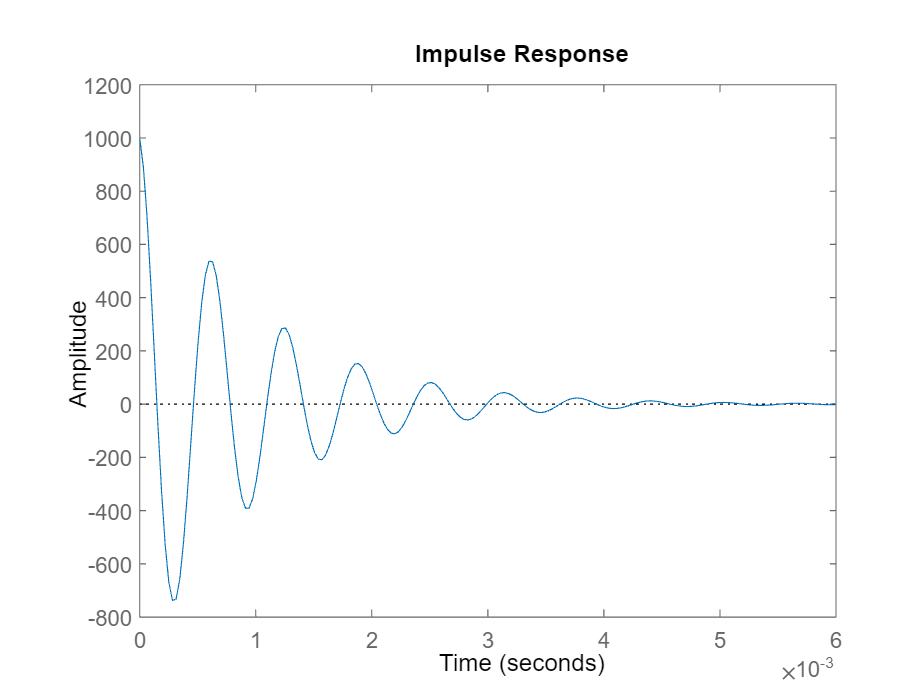

impulse(sys);

## Calculer les pôles

poles = pole(sys)

## Pulsation naturelle

Si conjugués complexes

omega_0 = abs(poles(1))

poles =  -1000.0000e+000 +  9.9499e+003i
 -1000.0000e+000 -  9.9499e+003i


Si non conjugués complexes

omega_0 = sqrt(poles(1) * poles(2))

omega_0 =     10.0000e+003

## Facteur d'amortissement

Si conjugués complexes

xi = - real(poles(1)) / omega_0

omega_0 =     10.0000e+003

Si non conjugués complexes

xi = - (poles(1) + poles(2))/(2*omega_0)

xi =    100.0000e-003

## Pulsation de résonnance

Si conjugués complexes

omega_r = abs(imag(poles(1)))

xi =    100.0000e-003

Si non conjugués complexes

omega_r = omega_0 * sqrt(1-xi^2)

omega_r =      9.9499e+003

omega_r =      9.9499e+003